Initialize variables for importing data

clc; clear all;
subject_num = 9003;
dof_type    = "multi";
filepath = "C:/Git/FES_Exo/data/data_collection/S" + subject_num + "/" + dof_type + "/";

files = dir(filepath);
files = files(3:end); % remove '.' and '..'

start_time = 2.0; % time when movement starts that we want to look at

warning('OFF', 'MATLAB:table:ModifiedAndSavedVarnames') % supress warning for variable names
for i = 1:length(files)
    T{i} = readtable(filepath + files(i).name);
    T{i} = T{i}(find(T{i}.time_s_>=start_time,1):end,:);
    T{i}.time_s_ = T{i}.time_s_ - T{i}.time_s_(1);
end

Combing through data to quantify features of data. Data collected here is:

- RMS Torque

- Max Torque

- RMS Error

for i = 1:length(T)
    fes_share(i)       = T{i}.fes_share__(1);
    
    elbow_rms_torque(i)    = rms(T{i}.elbow_fe_trq_Nm_);
    forearm_rms_torque(i)  = rms(T{i}.forearm_ps_trq_Nm_);
    wrist_fe_rms_torque(i) = rms(T{i}.wrist_fe_trq_Nm_);
    wrist_ru_rms_torque(i) = rms(T{i}.wrist_ru_trq_Nm_);
    
    elbow_max_torque(i)    = max(T{i}.elbow_fe_trq_Nm_);
    forearm_max_torque(i)  = max(T{i}.forearm_ps_trq_Nm_);
    wrist_fe_max_torque(i) = max(T{i}.wrist_fe_trq_Nm_);
    wrist_ru_max_torque(i) = max(T{i}.wrist_ru_trq_Nm_);
    
    elbow_rms_error(i)    = rms(T{i}.com_elbow_fe_rad_   - T{i}.act_elbow_fe_rad_);
    forearm_rms_error(i)  = rms(T{i}.com_forearm_ps_rad_ - T{i}.act_forearm_ps_rad_);
    wrist_fe_rms_error(i) = rms(T{i}.com_wrist_fe_rad_   - T{i}.act_wrist_fe_rad_);
    wrist_ru_rms_error(i) = rms(T{i}.com_wrist_ru_rad_   - T{i}.act_wrist_ru_rad_);
end

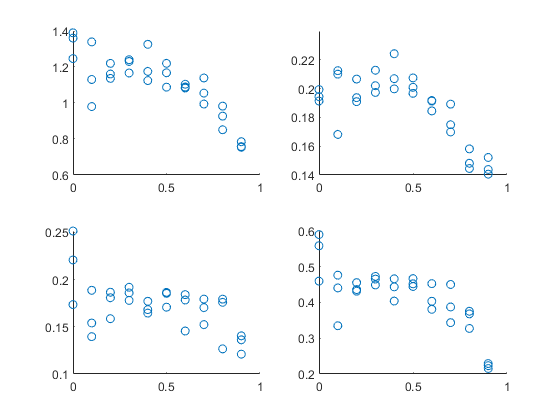


figure()
% Elbow
subplot(2,2,1)
scatter(fes_share,elbow_rms_torque)

% Forearm
subplot(2,2,2)
scatter(fes_share,forearm_rms_torque)

% Wrist FE
subplot(2,2,3)
scatter(fes_share,wrist_fe_rms_torque)

% Wrist RU
subplot(2,2,4)
scatter(fes_share,wrist_ru_rms_torque)

Formatting data so that it can be used for proper plotting including getting mean and std for the following features.

- RMS Torque

- Max Torque

- RMS Error

fes_amts_possible = 0:0.05:1.0;

i = 0;
for fes_amt = fes_amts_possible
    
    indices = abs(fes_share - fes_amt) < 0.001;
    
    if sum(indices) > 0
        i = i + 1;
        
        fes_amts(i) = fes_amt;
        
        elbow_rms_torque_local    = elbow_rms_torque(indices);
        forearm_rms_torque_local  = forearm_rms_torque(indices);
        wrist_fe_rms_torque_local = wrist_fe_rms_torque(indices);
        wrist_ru_rms_torque_local = wrist_ru_rms_torque(indices);
        
        elbow_rms_torque_std(i)     = std(elbow_rms_torque_local);
        elbow_rms_torque_mean(i)    = mean(elbow_rms_torque_local);
        forearm_rms_torque_std(i)   = std(forearm_rms_torque_local);
        forearm_rms_torque_mean(i)  = mean(forearm_rms_torque_local);
        wrist_fe_rms_torque_std(i)  = std(wrist_fe_rms_torque_local);
        wrist_fe_rms_torque_mean(i) = mean(wrist_fe_rms_torque_local);
        wrist_ru_rms_torque_std(i)  = std(wrist_ru_rms_torque_local);
        wrist_ru_rms_torque_mean(i) = mean(wrist_ru_rms_torque_local);
        
        
        elbow_rms_error_local    = elbow_rms_error(indices);
        forearm_rms_error_local  = forearm_rms_error(indices);
        wrist_fe_rms_error_local = wrist_fe_rms_error(indices);
        wrist_ru_rms_error_local = wrist_ru_rms_error(indices);
        
        elbow_rms_error_std(i)     = std(elbow_rms_error_local);
        elbow_rms_error_mean(i)    = mean(elbow_rms_error_local);
        forearm_rms_error_std(i)   = std(forearm_rms_error_local);
        forearm_rms_error_mean(i)  = mean(forearm_rms_error_local);
        wrist_fe_rms_error_std(i)  = std(wrist_fe_rms_error_local);
        wrist_fe_rms_error_mean(i) = mean(wrist_fe_rms_error_local);
        wrist_ru_rms_error_std(i)  = std(wrist_ru_rms_error_local);
        wrist_ru_rms_error_mean(i) = mean(wrist_ru_rms_error_local);
    end
end

fes_percent = fes_amts*100;


RMS torque plotting

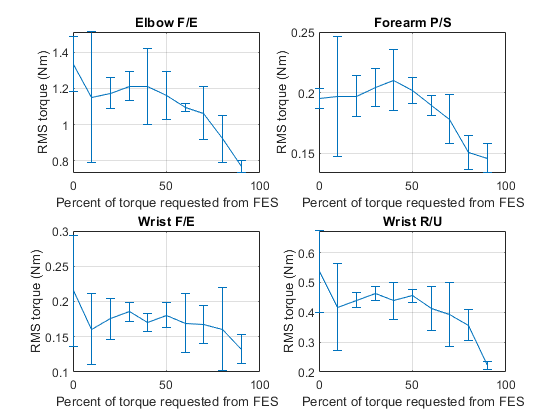

figure()

titles = ["Elbow F/E", "Forearm P/S", "Wrist F/E", "Wrist R/U"];
means =  [elbow_rms_torque_mean;  forearm_rms_torque_mean; wrist_fe_rms_torque_mean; wrist_ru_rms_torque_mean];
stds =  [elbow_rms_torque_std;  forearm_rms_torque_std; wrist_fe_rms_torque_std; wrist_ru_rms_torque_std];

for i = 1:4
    subplot(2,2,i)
    errorbar(fes_percent,means(i,:),2*stds(i,:))
    title(titles(i))
    xlabel("Percent of torque requested from FES")
    ylabel("RMS torque (Nm)")
    grid on
end

Max torque plotting

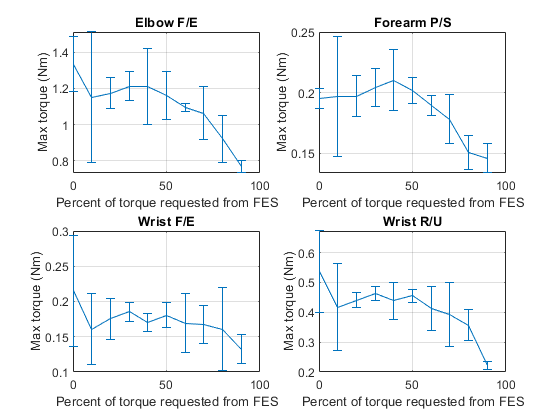

figure()

titles = ["Elbow F/E", "Forearm P/S", "Wrist F/E", "Wrist R/U"];
means =  [elbow_rms_torque_mean;  forearm_rms_torque_mean; wrist_fe_rms_torque_mean; wrist_ru_rms_torque_mean];
stds =  [elbow_rms_torque_std;  forearm_rms_torque_std; wrist_fe_rms_torque_std; wrist_ru_rms_torque_std];

for i = 1:4
    subplot(2,2,i)
    errorbar(fes_percent,means(i,:),2*stds(i,:))
    title(titles(i))
    xlabel("Percent of torque requested from FES")
    ylabel("Max torque (Nm)")
    grid on
end

RMS Error plotting

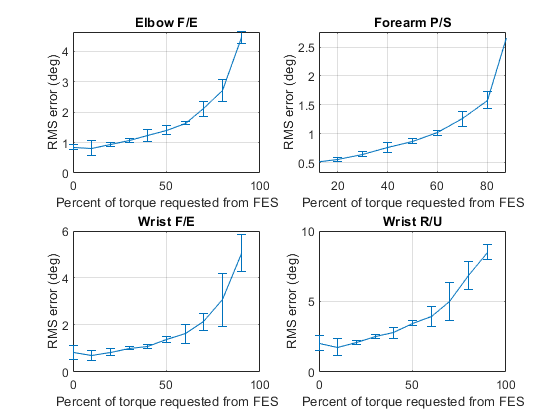

figure()

titles = ["Elbow F/E", "Forearm P/S", "Wrist F/E", "Wrist R/U"];
means =  [elbow_rms_error_mean;  forearm_rms_error_mean; wrist_fe_rms_error_mean; wrist_ru_rms_error_mean];
stds =  [elbow_rms_error_std;  forearm_rms_error_std; wrist_fe_rms_error_std; wrist_ru_rms_error_std];

for i = 1:4
    subplot(2,2,i)
    errorbar(fes_percent,rad2deg(means(i,:)),2*rad2deg(stds(i,:)))
    title(titles(i))
    xlabel("Percent of torque requested from FES")
    ylabel("RMS error (deg)")
    grid on
end